%The simple pixel operations
pic = imread("C:\Users\HP\Desktop\LabImages\Image\lena.bmp")

pic = 256×256 uint8 矩阵
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   138   133   134   134   136   132   130   130   131   134   128   127   131   128   128   130   130   128   136   138   142   146   150   150   149   148   143   132   119   111    88    78    65    61    60    66    70    69    73    74    75    74    73    76    73    73    76    73    76    76
   133   133   133   130   134   133   128   125   129   128   128   125  

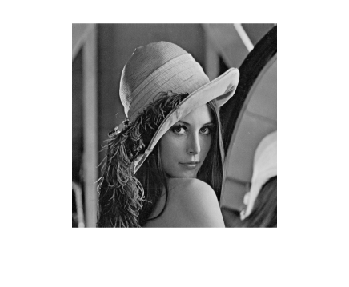

imshow(pic)

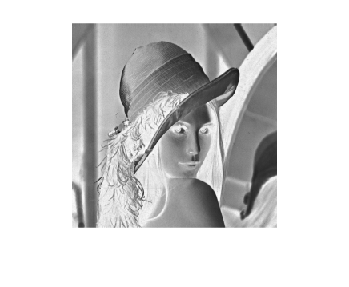

%1
pic_inverted = 255 - pic;
imshow(pic_inverted);

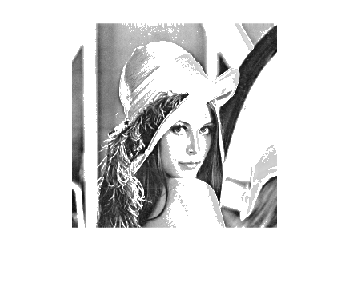

%2
pic_scaled = pic;

% For intensities < 100
pic_scaled(pic < 100) = 0;
% For intensities > 200
pic_scaled(pic > 200) = 255;
% For intensities in the range [100, 200]
index = (pic >= 100) & (pic <= 200);
pic_scaled(index) = ((pic(index) - 100)) * 2;

% Save the result
%pic_scaled = uint8(pic_scaled)
imwrite(pic_scaled, 'C:\Users\HP\Desktop\LabImages\Image\lena_inst_scale.bmp');

%3
pic_multiplied = double(pic);  % Convert to double for arithmetic operations
% For intensities in the range [0, 100]
index1 = (pic >= 0) & (pic <= 100);
pic_multiplied(index1) = pic_multiplied(index1) * 2;

% For intensities in the range [100, 200]
index2 = (pic > 100) & (pic <= 200);
pic_multiplied(index2) = pic_multiplied(index2) * 3;

% Handle overflow
pic_multiplied(pic_multiplied > 255) = 255;
pic_multiplied = uint8(pic_multiplied);  % Convert back to uint8
imshow(pic_multiplied);

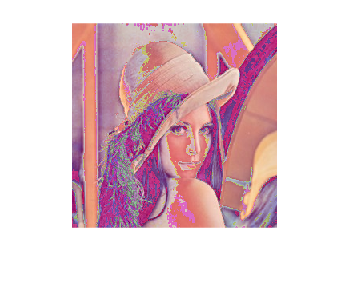


%4
pic2 = imread('C:\Users\HP\Desktop\LabImages\Image\lena_colour.jpg');
if size(pic2, 3) == 3  % Check if it's a color image
    pic2_gray = rgb2gray(pic2);
else
    pic2_gray = pic2;
end
pic_2 = double(pic2); 
% For intensities in the range [0, 100]
index2 = (pic2 >= 0) & (pic2 <= 100);
pic_2(index2) = pic_2(index2) * 2;

% For intensities in the range [100, 200]
index22 = (pic > 100) & (pic <= 200);
pic_multiplied(index22) = pic_multiplied(index22) * 3;

% Handle overflow
pic_2(pic_2 > 255) = 255;
pic_2 = uint8(pic_2);  % Convert back to uint8
imshow(pic_2)

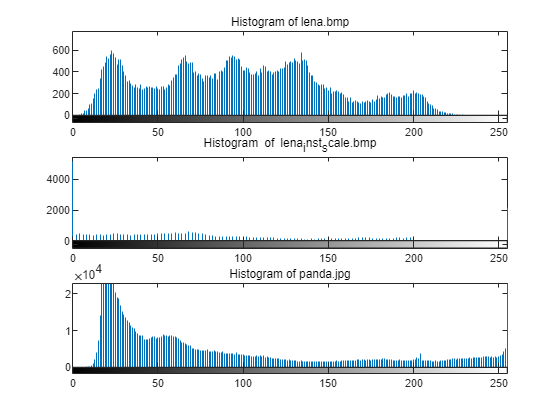

%The histogram and its comparison
%1
% pic1 = imread("C:\Users\HP\Desktop\LabImages\Image\lena.bmp")
% pic2 = imread( "C:\Users\HP\Desktop\LabImages\Image\lena_inst_scale.bmp")
% pic3 = imread( "C:\Users\HP\Desktop\LabImages\Image\panda.jpg")
lena = imread("C:\Users\HP\Desktop\LabImages\Image\lena.bmp");
lena_inst_scale = imread( "C:\Users\HP\Desktop\LabImages\Image\lena_inst_scale.bmp");
panda = imread( "C:\Users\HP\Desktop\LabImages\Image\panda.jpg");
figure;
subplot(3,1,1);
imhist(lena);
title('Histogram of lena.bmp');

subplot(3,1,2);
imhist(lena_inst_scale);
title('Histogram of lena_inst_scale.bmp');

subplot(3,1,3);
imhist(panda);
title('Histogram of panda.jpg');

% figure;
% imhist(pic2)

%2
% figure;
% imhist(lena, 25);  
%标准化
% h1 = lena/sum(lena);
% h2 = lena_inst_scale/sum(lena_inst_scale);
% h3 = panda/sum(panda)
%3如何计算卡方

h1 = histcounts(lena(:), 256, 'Normalization', 'probability');
h2 = histcounts(lena_inst_scale(:), 256, 'Normalization', 'probability');
h3 = histcounts(panda(:), 256, 'Normalization', 'probability');

chi_square_dist_lena_lenaInst = sum((h1-h2).^2 ./(h1+h2+eps))

chi_square_dist_lena_lenaInst = 1.2107

chi_square_dist_lena_panda = sum((h1-h3).^2 ./(h1+h3+eps))

chi_square_dist_lena_panda = 0.5074

chi_square_dist_lenaInst_panda = sum((h2-h3).^2 ./(h2+h3+eps))

chi_square_dist_lenaInst_panda = 1.2111


% Euclidean distance 
euclidean_distance_h1_h2 = sqrt(sum((h1 - h2).^2))

euclidean_distance_h1_h2 = 0.5306

euclidean_distance_h1_h3 = sqrt(sum((h1 - h3).^2))

euclidean_distance_h1_h3 = 0.0937

euclidean_distance_h2_h3 = sqrt(sum((h2 - h3).^2))

euclidean_distance_h2_h3 = 0.5356


%intersection distance metric
intersection_distance_h1_h2 = sum(min(h1, h2))

intersection_distance_h1_h2 = 0.3307

intersection_distance_h1_h3 = sum(min(h1, h3))

intersection_distance_h1_h3 = 0.5567

intersection_distance_h2_h3 = sum(min(h2, h3))

intersection_distance_h2_h3 = 0.3215


%4% Use  function custom_histogram
figure;
lena = imread("C:\Users\HP\Desktop\LabImages\Image\lena.bmp")

lena = 256×256 uint8 矩阵
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   138   133   134   134   136   132   130   130   131   134   128   127   131   128   128   130   130   128   136   138   142   146   150   150   149   148   143   132   119   111    88    78    65    61    60    66    70    69    73    74    75    74    73    76    73    73    76    73    76    76
   133   133   133   130   134   133   128   125   129   128   128   125 

title('Histogram ');
h_lena = custom_histogram(lena, 256)

h_lena =          0         0         0    0.0000    0.0001    0.0002    0.0003    0.0006    0.0006    0.0009    0.0015    0.0017    0.0023    0.0030    0.0036    0.0037    0.0052    0.0065    0.0068    0.0075    0.0083    0.0080    0.0085    0.0091    0.0087    0.0081    0.0071    0.0079    0.0079    0.0070    0.0061    0.0057    0.0048    0.0049    0.0045    0.0042    0.0039    0.0043    0.0040    0.0037    0.0044    0.0036    0.0038    0.0041    0.0039    0.0041    0.0039    0.0039    0.0038    0.0040


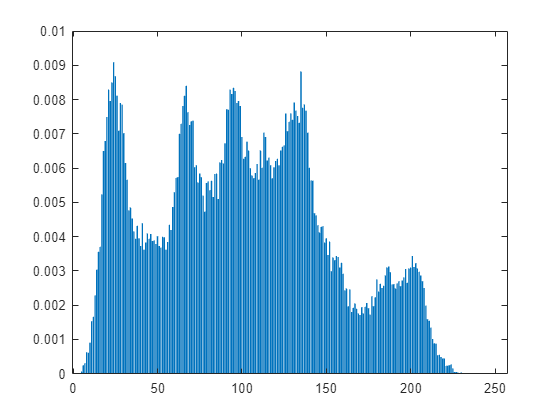

bar(h_lena)

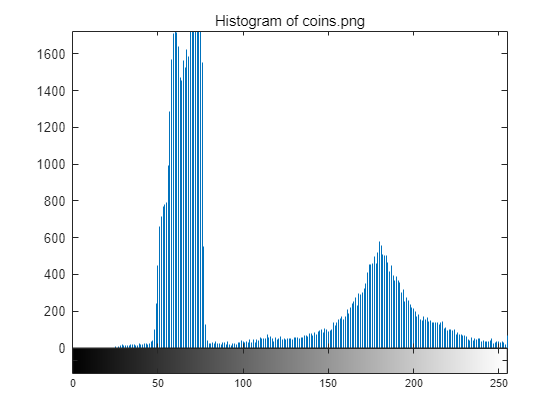

%Thresholding
%1
img = imread('C:\Users\HP\Desktop\LabImages\Image\coins.png');
figure;
imhist(img);
title('Histogram of coins.png');

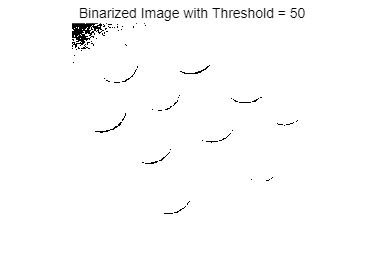

%2
binarized_img = img > 50;
figure;
imshow(binarized_img);
title('Binarized Image with Threshold = 50');

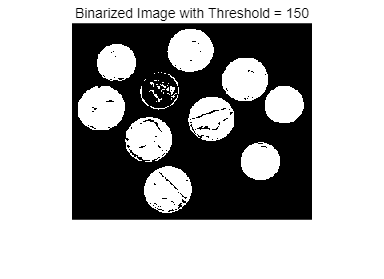


%3
threshold_T = 150;
binarized_img_T = img > threshold_T;
figure;
imshow(binarized_img_T);
title(['Binarized Image with Threshold = ', num2str(threshold_T)]);

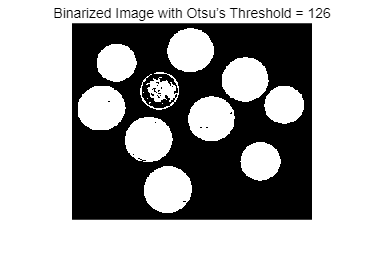


%4
otsu_threshold = graythresh(img);  
otsu_threshold_255 = otsu_threshold * 255;  % Scaling to [0, 255]

binarized_img_otsu = img > otsu_threshold_255;
figure;
imshow(binarized_img_otsu);
title(['Binarized Image with Otsu’s Threshold = ', num2str(otsu_threshold_255)]);

disp(['Chosen threshold in step 3: ', num2str(threshold_T)]);

Chosen threshold in step 3: 150


disp(['Otsu’s threshold: ', num2str(otsu_threshold_255)]);

Otsu’s threshold: 126


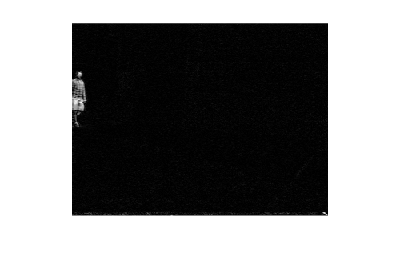

%Frame differencing and background extraction
%1
folder_path = 'C:\Users\HP\Desktop\LabImages\WalkSequence\Greyscale'; 
img_files = dir(fullfile(folder_path, '*.png')); 
num_files = length(img_files);
img_sequence = cell(1, num_files);

for i = 1:num_files
    img_sequence{i} = imread(fullfile(folder_path, img_files(i).name));
end
%2
frame_diff = double(img_sequence{11}) - double(img_sequence{1});
imshow(abs(frame_diff), []);

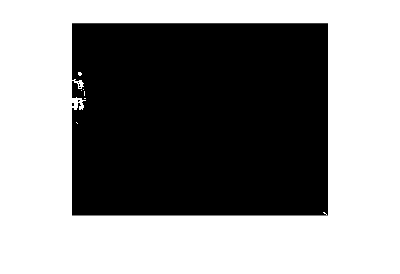

threshold_diff = 90;  
binarized_diff = abs(frame_diff) > threshold_diff;
imshow(binarized_diff);


%3
B = zeros(size(img_sequence{1}));
for i = 1:num_files
    B = B + double(img_sequence{i});
end
B = B / num_files

B =   156.2200  155.9400  159.0000  158.2600  154.3400  134.5000  102.4800   91.1400   99.9800  107.6400  111.3400  113.3400  117.0400  103.2000   73.3400   56.8000   45.7800   30.7600   25.8600   28.7200   34.2000   41.1800   47.3600   53.9600   61.4000   67.4400   65.7800   51.6200   45.8000   41.5400   30.5200   29.9400   31.5000   31.5000   31.7400   31.7800   31.6800   31.1200   30.6800   31.7600   39.0200   57.7200   76.0200   82.7200   74.7400   51.1600   31.6800   36.8600   58.5200   86.1200
  156.6600  156.7800  158.1200  157.1000  159.2400  159.0000  141.6800  118.9600  105.4600   98.9600   98.0400  101.7600  110.8800  110.8200  106.2200  105.3000   90.5800   60.8000   36.7800   29.5600   31.6400   33.2600   33.8600   38.6400   47.6800   58.0000   61.4600   52.7800   49.1400   42.0200   30.2000   30.7400   32.0200   32.5200   33.2000   32.7600   30.7800   28.5600   28.9800   30.8800   32.5800   40.1200   55.7600   74.0600   82.4800   71.3800   50.1800   33.9400   29.2800   48

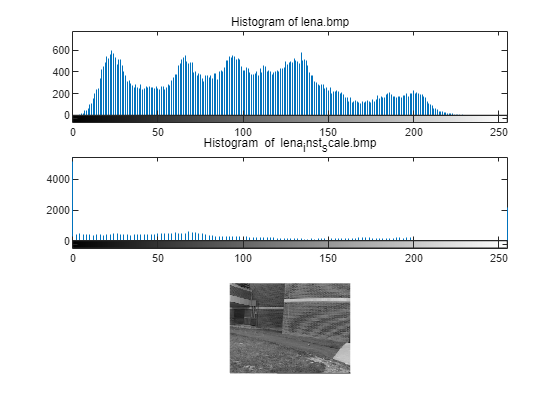

imshow(uint8(B));


diff_sequence = cell(1, num_files)

diff_sequence = 1×50 cell 数组
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


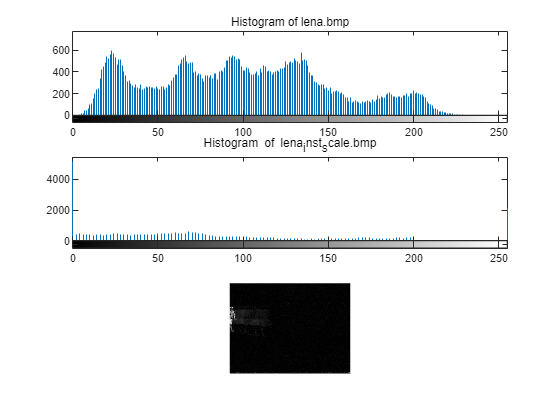

for i = 1:num_files
    diff_sequence{i} = double(img_sequence{i}) - B;
end
imshow(abs(diff_sequence{9}), [])

foreground =  -151.0000 -151.0000 -156.0000 -157.5200 -151.6800 -128.0000  -93.9600  -91.0000  -94.0000 -103.0000 -108.0000 -113.0000 -114.0800  -97.4000  -66.6800  -53.6000  -43.5600  -27.5200  -23.7200  -28.4400  -34.0000  -40.0000  -47.0000  -52.0000  -61.0000  -67.0000  -65.5600  -46.2400  -43.6000  -39.0800  -30.0000  -25.0000  -30.0000  -29.0000  -28.0000  -29.0000  -30.0000  -30.0000  -28.3600  -27.5200  -38.0400  -57.4400  -74.0400  -79.4400  -68.4800  -45.3200  -31.3600  -34.0000  -56.0000  -77.0000
 -154.0000 -155.0000 -158.0000 -156.2000 -157.4800 -157.0000 -139.3600 -118.9200 -104.0000  -98.9200  -97.0000 -101.0000 -110.0000 -110.0000 -105.0000 -104.0000  -90.0000  -59.6000  -36.5600  -27.0000  -31.0000  -32.5200  -32.7200  -37.2800  -47.3600  -57.0000  -60.0000  -52.5600  -48.2800  -40.0000  -27.0000  -27.0000  -30.0000  -32.0000  -32.4000  -32.0000  -29.0000  -26.0000  -28.9600  -30.7600  -31.1600  -39.2400  -55.5200  -73.0000  -80.0000  -70.7600  -49.3600  -31.8800  -28.

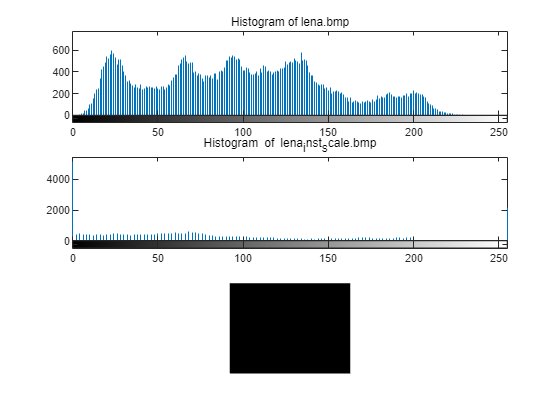


% threshold_segment = 12; 
% foreground = abs(diff_sequence{1}) > threshold_segment
% imshow(foreground)


function hist_array = custom_histogram(img, bins)
    hist_array = zeros(1, bins);
    bin_width = 256 / bins;
    for i = 1:numel(img)
        bin_index = floor(double(img(i)) / bin_width) + 1;
        hist_array(bin_index) = hist_array(bin_index) + 1;
    end
    hist_array = hist_array / numel(img);  % Normalize to get probabilities
end














